load Xscell, t

addpath(genpath('../'))

choose experiments from Xscell to use in regression

exps = 1; % number of exps
NN = size(Xscell{1},1); % number of particles per exp

choose histogram grid resolution

numx = 80 + 1;
norml = 'pdf';
numsdv = 10;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
scoord = 0;

set extrinsic noise level

extrinsic_nz=0;
Xsnz = [extrinsic_nz 1];

compute histogram

get_particle_distrib;

ET_load_data = 0.1007 


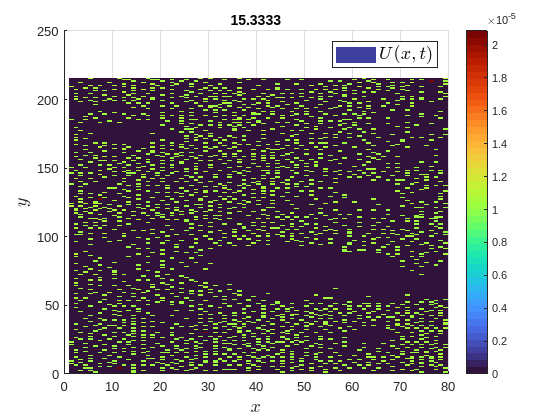

plotgap=5;
plot_distrib;

Choose model library

%local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];%[[2 2 0 0];[2 0 2 0]];
custom_remove = [];
toggle_comb = 1;

%local non-autonomous operators
driftpolys=[0:1]; drifttrigs=[];
diffpolys=[0:2]; difftrigs=[]; crossdrift=0;

%non-local operators
dim = size(Xscell{1},2)+1;
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:5],'Sing',[0],'Exp',[],'Singeps',[0.02],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 0.0687 


Set discretization

phi_class = {1,1};
sm_x = 4;
sm_t = 4;

%%% manually set test function params
p_x = 5; mxs = floor(numx/4);
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 15;
tau_t = []; k_t = []; tauhat_t = [];

% %%% set test fcn params using cornerpoint
% tauhat_x = 6; tau_x = 10^-4;
% p_x = []; mxs = 1;
% tauhat_t = 4; tau_t = 10^-4;
% p_t = []; mts = 1;

% rescale coordinates and/or use approx. variance for improved conditioning
scales = 2;
covtol = 0; 

% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-2;

set_discretization;

ET_setdisc = 0.4009 


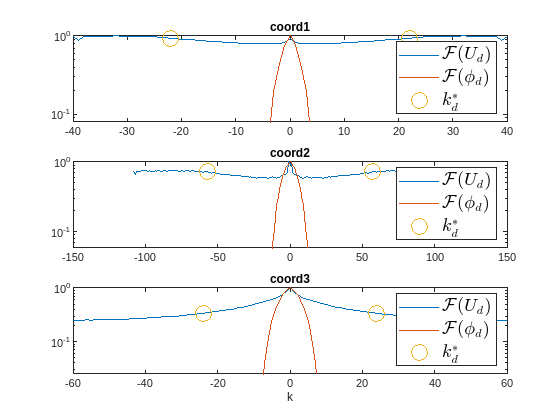


toggle_plot_fft = 1;
plot_Ufft;

Build linear systems

build_Gb;

Solve linear system

lambda = 10.^(linspace(-6, 0, 400));
gamma_tol = Inf;
alpha = 1/(0.02*size(G,2)+1);
maxits = Inf;
sparsity_scale = 0;
excl_tags={};%{'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=1e-5;
tol = 10^-10;
maxQPits = 1000; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 2.5195 


get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = 0.0766858([x.^1.*y.^0.*t.^0]u^1)_{x} + 1.50673([x.^1.*y.^0.*t.^0]u^1)_{lap} + -0.493993([x.^0.*y.^1.*t.^0]u^1)_{lap}
Relative Res: ||b-G*W||_2/||b||_2 = 6.60e-01TP Score = NaN
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 20 15 
[s_x s_t] = 5 3 
[p_x p_t] = 5 3 
 scales = 1.00e+00 3.18e-02 3.18e-02 5.00e-01 
      
Total particles = 3881 
Size of dataset = 80 216 119 
Size G = 172 49 
Cond G = 1.18e+24
[lambda_hat gamma] = 1.802e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 3 
 
ET_load_data = 0.1007 
ET_build_lib = 0.0687 
ET_setdisc = 0.4009 
ET_build_Gb = 0.9973 
ET_solve_sparse_reg = 2.5195 
Elapsed time WSINDy = 4.0871 


Display loss

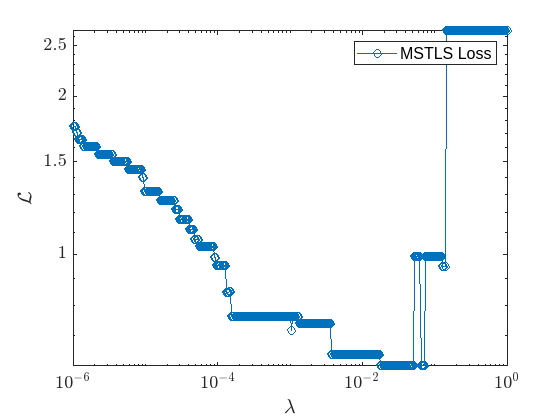

toggle_plot_loss = 1;
plot_loss;

Display drift/diffusion

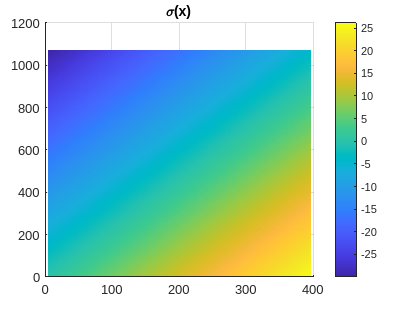

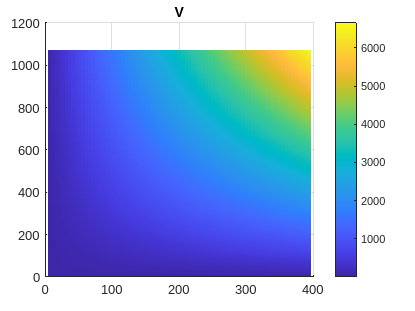

toggle_plot_drift = 1;
plot_driftdiff;

Display interaction force

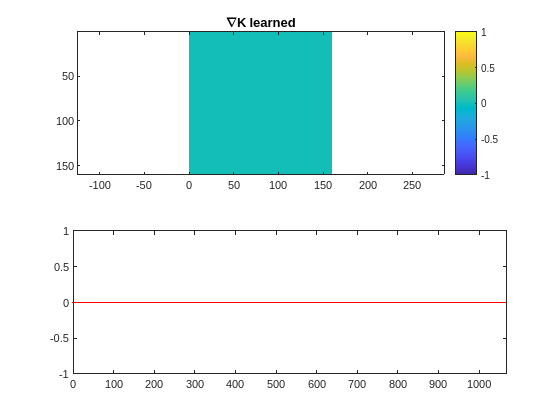

toggle_plot_IPforce = 1;
plot_K